## **Polynomiální regrese gradientní metodou největšího spádu:**

Výchozí materiál: An overview of gradient descent optimization algorithms

Metoda největšího spádu je iterační metoda a její myšlenka je velmi prostá. Stejně jako v analitickém řešení polynomiální regrese, tak i zde řešíme skrze metodu nejmenších čtverců, tudíž zásislost kvadratického funkcionálu na zkoumané soustavě je vždy paraboloid. Hledání aproximace poté vlastně představuje hledání minimální hodnoty (v našem případě hodnoty koeficientů polynomu) tohoto paraboloidu, jinými slovy hledáme globální minimum této funkce. Jelikož se jedná o paraboloid, tak toto minimum lze nalézt pomocí gradientních metod. Gradientní metody obecně pracují následnovně. Je vybrán náhodný bod a je pro tento bod spočten gradient. Gradient ukazuje směr největšího růstu v daném bodě, tudíž záporný gradient ukazuje naopak směr největšího spádu. Můžeme tedy upravit hodnoty zkoumané soustavy (v našem případě koeficienty polynomu) ve směru gradientu a tím se přiblížit optimálnější aproximaci. Tyto kroky můžeme opakovat tak dlouho, dokud postupnými kroky nedojdeme až do minima funkce. Postup se snaží znázornit následující obrázek, kde černě jsou znázorněny vrstevnice paraboloidu a modře postupné kroky proti směru gradientu, kterými jsme dosáhli globálního minima této fuknce.

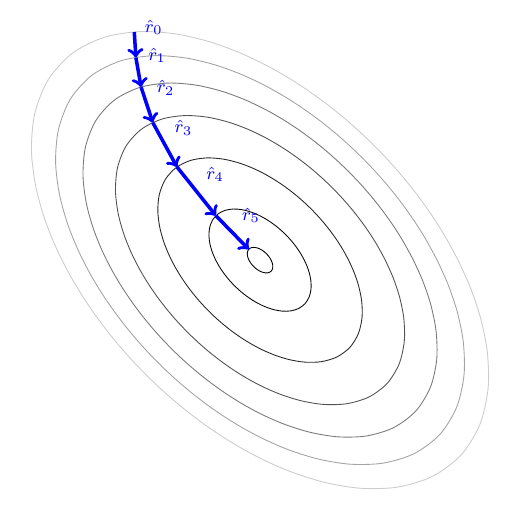

Tento postup může skýtat několik komplikací. Jednou z nich je otázka nastavení délky kroku, který děláme po výpočtu gradientu. Pokud bude krok moc dlouhý, je možné, že se budeme od optimálního řešení spíše vzdalovat a naopak pokud bude krok příliš krátký, bude trvat neúměrně dlouho, než do optima dojdeme. Stejně tak i problémem může být, pokud má paraboloid ošklivý tvar (uzký). Při takovém tvaru paraboliodu totiž neexistuje krok, který by směřoval přímo k minimu a dochází k tzv. cik cak efektu. Některé soustavy dokonce mohou mít závislost kvadratického funkcionálu takovou, že obsahují lokální minima, v takovém případě mohou gradientní metody naprosto selhat na nalezení optimální aproximace. Kvůli těmto problémům byla vyvinuta celá řada různých metod vylepšujících základní metodu největšího spádu.

Základní vzoreček vystihující metodu největšího spádu může vypadat např. takto: $w=w-\left(\eta \nabla f_{\left(\theta \right)} \right)\;$, kde $w$ jsou koeficienty polynomu, $\eta$ je učící faktor (délka kroku) a $\nabla f_{\left(\theta \right)}$ je gradient kvadratického funkcionálu zkoumané soustavy (to je ten paraboloid). 

Základní rozdělení metod největšího spádu může být podle toho, jaká tréninková data používá. V této funkci používám pouze tzv. Batch gradient descent (BGD -"Dávková" metoda největšího spádu), která se vyznačuje tím, že výpočet provádí na všech vstupních datech. Ale pokud bych měl vstupních dat příliš velké množství, mohu využít jiné varianty. Např. použít metodu Stochastic gradient descent (SGD - Náhodná metoda největšího spádu), která vybírá ze vstuních dat jen určitá za pomocí náhodného výběru a výpočet provádní na nich. Určitou střední cestou může být Mini batch gradient descent (mBGD - "Mini-dávková" metoda největšího spádu), která také používá jen určité vstupní data na základě náhodného výběru, ale místo jednotlivých vstupních dat si vybírá zhluky dat (skupiny sousedících), čímž se dosáhne zpravidla lepších výsledků, než u jednoduché SGD.

Dělení podle použitých tréninkových dat:

- BGD - Batch gradient descent

- SGD -  Stochastic gradient descent

- mBGD - Mini batch gradient descent

Kód níže ukazuje pouze základní metodu největšího spádu, ale mohl by obsahovat různá vylepšení. Např:

- Momentum - směr klesání není spočten pouze na základě gradientu v současném bodě, ale také podle gradientu v bodě předešlém. Díky tomu je možné eliminovat cik cak efekt. Na druhou stranu musím kromě délky kroku (učící faktor) vybrat také hodnotu, jak moc silný efek bude mít gradient v předešlém bodě na ten současný (typicky se značí $\lambda$)  

- RMSprop - změna parametru učení (délka kroku) na základě znaménka gradientu. Pokud se od posledního výpočtu znaménko gradientu změní, krok se zmenšuje, pokud se naopak zneménko změnilo, vypadá to, že se pohybuji kolem minima a tak krok změnším.

- ADAM - adaptivně mění délku kroku...  TODO

Např. vzoreček pro Momentum by vypadal $\theta =\theta -\left(\gamma \left(\eta \nabla f_{\left(\theta -1\right)} \right)+\eta \nabla f_{\left(\theta \right)} \right)\;$. Vzoreček je prakticky stejný jako pro obyčejnou metodu největšího spádu, jen nám zde přibyl člen $\gamma \left(\eta \nabla f_{\left(\theta -1\right)} \right)$. Tento člen obsahuje výpočet gradientu z předešlého kroku a přenásobuje ho určitým faktorem $\gamma$ (většinou hodnota 0.9 nebo tak nějak). Následně je tento člen přičten k výpočtu gradientu v součaném bodě a tím je deinován další bod $w$.

Takže konkrétně k této metodě. V příkladu "Polynomial_regression_analytically" jsme si kompletně odvodili vztah pro obecnou aproximaci závislou na různývh bázových funkcích. Pro připomentí:


$$\mathit{\mathbf{W}}={\left({\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} \phi_{\left(\mathit{\mathbf{x}}\right)} \right)}^{-1} -{\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} {\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)}$$


,kde matice $\phi_{\left(\mathit{\mathbf{x}}\right)}$ jsou bázové funkce modelu, které jsou vytvořeny na základě vstupů $x$ a požadovaném řádu polynomu $M$. Stejně jako u analicitého řešení, tak i zde tento vzorec využijeme:

function [t_w,w,e,E_w,iter] = Batch_gradient_descent(x, t, M, q, max_iter)
%   x:          vzorkovací čas
%   t:          naměřenné vzorky
%   M:          řád polynomu
%   q:          pokud přensot řešení bude menší než tato hodnota, řešení se vrací a metoda končí
%   max_iter    pokud se ani do tohoto počtu iterací nenajde řešení, metoda končí a vrací se poslední zjištěné řešení
%   t_w:        body aproximace pro vstupní hodnoty x
%   w_aprox:    koeficienty aproximačního polynomu
%   e:          rozdíl bodů aproximační funkce a naměřených výstupů
%   E_w:        velikost druhých mocnin rozdílů e (metoda nejmenších čtverců)


Do $N$je uložen počet vzorků. 

N = length(x); 

S maticí výstupů budu chtít pracovat jako se sloupovým vektorem.

t = t';                

Nyní dochází k vytvoření bázové matice $\phi_{\left(\mathit{\mathbf{x}}\right)}$. Pokud bych chtěl jiné bázové funkce, tak budu kód měnit tady.

Phi = zeros(N,M+1);
for j = 0:M
    for i = 0:N-1
        Phi(i+1,j+1) = x(i+1)^j;
    end
end

t = Phi'*t;
Phi = Phi'*Phi;

w = zeros(M+1,1); % nastavení počátečního bodu do nuly (mohl bych nastavovat např. náhodně)
iter = max_iter;   % iter je proměnná, která vyjadřuje počet iterací, které bylo zapotřebí k výpočtu pro zadanou hodnotu tolerance (je nastavena na maximum, ale pokud se algoitmus dostane k tolaranci dříve, tato proměnná je přepsána)

for i = 1:max_iter
    % 1 rozdíl aproximace od naměřených dat
    r = t - Phi*w;
    % 2  
    alpha = (r'*r)/(r'*Phi*r);
    % 3
    w = w + alpha*r;
    t_w = Polynomial_evaluation(x,w);     % nyní vypočítám výstupní hodnoty pro vstupní hodnoty dosazené do polynomu s koeficienty, které jsme vypočítali výše 
    [E_w,e] = Least_squares_method(t_w,t);      % abych zjistil jak moc je moje nová aproximace přesné, vypočítám MNČ oproti původním vstupním datům
    
    if E_w < q          % hodnotu získanou MNČ porovnám s požadovanou tolerancí, a pokud byla požadovaná tolerance dosažena, tak mohu hodnotu koeficientů vrátit
        iter = i;
        break;
    end
end
end